clear; close all;

% Demo dynamics
N = 25;
P = tril(toeplitz(randn(N,1)));

% Reference
ur = randn(N,1);
r  = P*ur;

% Setup IO-MOLE
dyn_func = @(u)P*u;
io_mole = CIOMOLE(dyn_func);

% Initial input trajectory
u0 = 0.01*randn(N,1);

% Number of trials
J = 15;

% Run IO-MOLE
tic;
[ev, ec, yc, uc] = io_mole.run_iomole(r, u0, J);
toc;

Elapsed time is 0.952731 seconds.


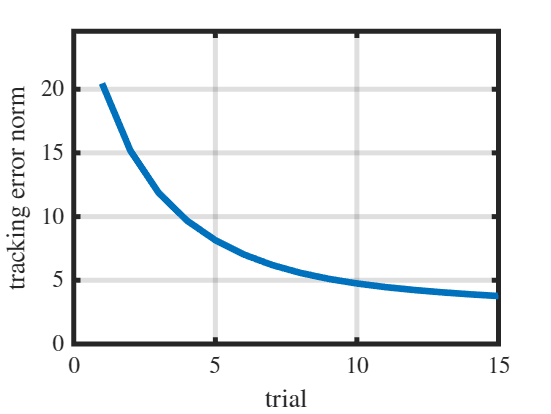


% Plot error norms
figure;
plot(ev);
xlabel('trial');
ylabel('tracking error norm');
ylim([0, ev(1)*1.2]);

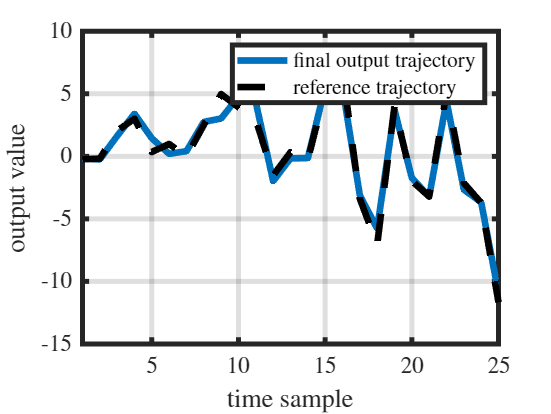


% Plot reference and final output trajectory
figure;
plot(yc{end,1}); hold on;
plot(r, '--', 'Color', 'black');
xlabel('time sample');
ylabel('output value');
legend('final output trajectory', 'reference trajectory');
xlim([1,N]);